close all
% 2.1.1

% Copy data from provided table
pd = [0.1,0.2,0.5,1,2,4,8,16];
tc1 = [6,3,2,1.7,1.5,1.4,1.4,1.4];
tc2 = [8,5,2,1.5,1.0,0.7,0.6,0.6];
tc3 = [4,2,1,0.6,0.4,0.3,0.3,0.3];

% Computation of rheobase and chronaxie values for each curve
rheo1 = min(tc1);
chro1 = 0.2; % Estimated pulse duration when current = 2*rheo1 ~= 3

rheo2 = min(tc2);
chro2 = 1.5; % Approximated pulse duration when current = 2*rheo2 ~= 1.25
             % 1.2 is roughly halfway between 1 and 1.5, so chro2 = the mean
             % of the puse duration when I = 1 and when I = 1.5

rheo3 = min(tc3);
chro3 = 1; % Exact pulse duration when current = 2*rheo3 = 0.6

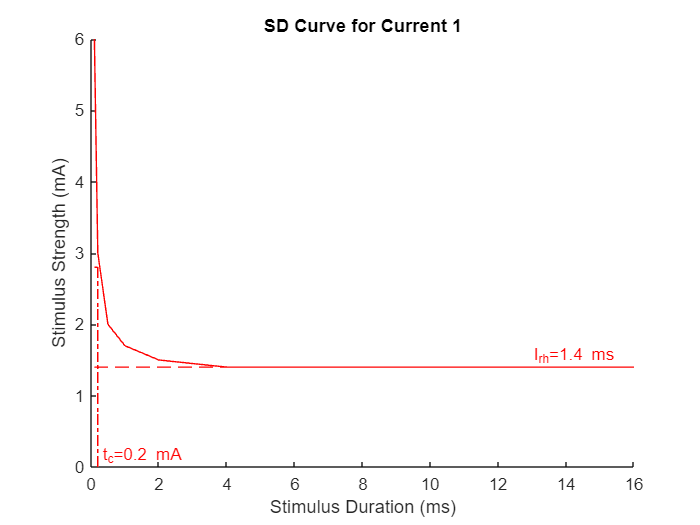

% SD Curve for Current 1
close all
hold on
plot(pd,tc1,'r')
plot(pd,linspace(rheo1,rheo1,length(pd)),'--r')
text(13,rheo1+.15,"I_{rh}="+num2str(rheo1)+ " ms",color='r',FontSize=10)
plot(linspace(min(pd),chro1,length(pd)),linspace(2*rheo1,2*rheo1,length(pd)),'-.r')
plot(linspace(chro1,chro1,length(pd)),linspace(0,2*rheo1,length(pd)),'-.r')
text(chro1+0.1,0.15,"t_c="+num2str(chro1)+" mA",color='r',FontSize=10)

xlabel("Stimulus Duration (ms)");
ylabel("Stimulus Strength (mA)");
title("SD Curve for Current 1");
hold off

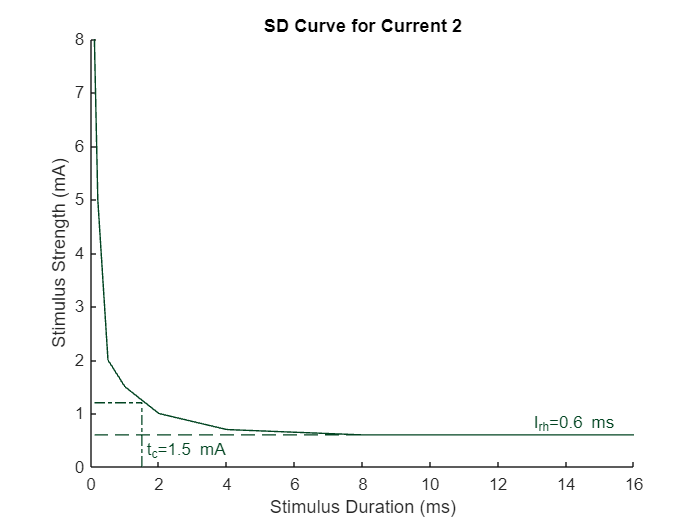

% SD Curve for Current 2
close all
hold on
plot(pd,tc2,color='#014421')
plot(pd,linspace(rheo2,rheo2,length(pd)),color='#014421',LineStyle='--')
text(13,rheo2+.2,"I_{rh}="+num2str(rheo2)+ " ms",color='#014421',FontSize=10)
plot(linspace(min(pd),chro2,length(pd)),linspace(2*rheo2,2*rheo2,length(pd)),color='#014421',LineStyle='-.')
plot(linspace(chro2,chro2,length(pd)),linspace(0,2*rheo2,length(pd)),color='#014421',LineStyle='-.')
text(chro2+0.1,0.3,"t_c="+num2str(chro2)+" mA",color='#014421',FontSize=10)

xlabel("Stimulus Duration (ms)");
ylabel("Stimulus Strength (mA)");
title("SD Curve for Current 2");
hold off

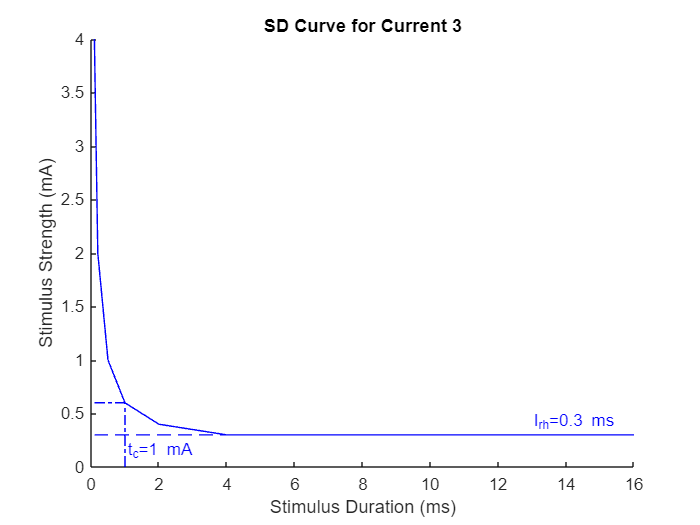

% SD Curve for Current 3
close all
hold on
plot(pd,tc3,'b')
plot(pd,linspace(rheo3,rheo3,length(pd)),'--b')
text(13,rheo3+.125,"I_{rh}="+num2str(rheo3)+ " ms",color='b',FontSize=10)
plot(linspace(min(pd),chro3,length(pd)),linspace(2*rheo3,2*rheo3,length(pd)),'-.b')
plot(linspace(chro3,chro3,length(pd)),linspace(0,2*rheo3,length(pd)),'-.b')
text(chro3+0.04,0.15,"t_c="+num2str(chro3)+" mA",color='b',FontSize=10)

xlabel("Stimulus Duration (ms)");
ylabel("Stimulus Strength (mA)");
title("SD Curve for Current 3");
hold off

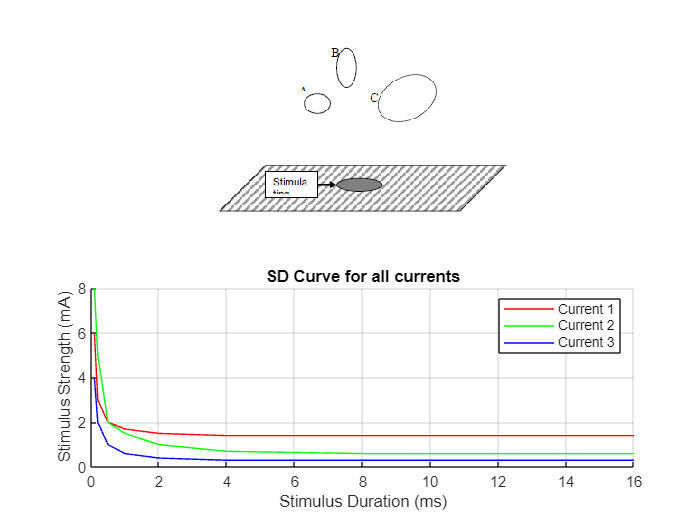

% 2.1.2

% Redefine data and constants from 2.1.1
pd = [0.1,0.2,0.5,1,2,4,8,16];
tc1 = [6,3,2,1.7,1.5,1.4,1.4,1.4];
tc2 = [8,5,2,1.5,1.0,0.7,0.6,0.6];
tc3 = [4,2,1,0.6,0.4,0.3,0.3,0.3];

rheo1 = min(tc1); chro1 = 0.2;
rheo2 = min(tc2); chro2 = 1.5;
rheo3 = min(tc3); chro3 = 1;

% Create plot to compare the 3 SD curves
close all
subplot(2,1,1)
img = imread("Q2_1_2_soma.png");
imshow(img)

subplot(2,1,2)
hold on
plot(pd,tc1,'r')
plot(pd,tc2,'g')
plot(pd,tc3,'b')

xlabel("Stimulus Duration (ms)");
ylabel("Stimulus Strength (mA)");
title("SD Curve for all currents");
legend("Current 1", "Current 2", "Current 3")
grid on
hold off

% Since the SD curve for the cell induced by current 3 has the smallest
% threshold and smallest stimulation duration, it is the most excitable.
% Cell C has the largest soma, and is thus the most excitable of the 3
% cells. Therefore, current 3 corresponds to the SD curve of Cell C.

% Since the rheobase of the cell induced by current 1 is greater than the
% rheobase of the cell induced by current 2, the cell induced by current 2
% is more excitable than the cell induced by current 1. Cells with larger 
% somas are more excitable than those with smaller somas, and Cell B has a
% larger soma than Cell A. Therefore, current 1 corresponds to the SD curve
% of cell A and current 2 corresponds to the SD curve of cell B.

% The SD curve for current 1 corresponds to cell A
% The SD curve for current 2 corresponds to cell B
% The SD curve for current 3 corresponds to cell C

% 2.1.3

% In order to selectively stimulate Cell A, we would need to introduce a
% current which is both above the rheobase for Cell A and below the
% rheobase for Cells B and C. Since the rheobase of Cell A is larger than
% that of Cells B and C, any current we supply that would be sufficient to
% activate Cell A would also activate Cells B and C. Therefore, it is NOT
% possible to selectively stimulate Cell A given the locations of the cells
% and stimulating electrode.

% 2.2a

% We know that charge density = Q/A and Q = IdelT, so we can compute charge
% density as follows;
I = 80e-6; % Current (A)
delT = 1;  % ms
A = pi*(30e-4)^2;
sigma = I*delT/A

sigma = 2.8294

% Therefore, if 80 uA of current is applied with a pulse width of 1 ms, the
% charge density of this electrode is 2.82 mC/cm^2.

% 2.2b

% See 2.2a

% 2.2c

% The electrochemical safe charge density for a Pt electrode if 0.35
% mC/cm^2. Since 2.82 mC/cm^2 > 0.35 mC/cm^2, this is NOT an
% electrochemically safe stimulation.

% 2.2d(a)

% If 80 uA is used and we want to stay electrochemically safe with a charge
% density < 0.35 mC/cm^2, then our maximial pulse width can be computed as
% follows:

ESL_plat = 0.35; % mC/cm^2
I = 80e-6; % Current (A)
A = pi*(30e-4)^2; % cm^2

delT = ESL_plat*A/I

delT = 0.1237

% Our maximal pulse width under these conditions is 0.1237 ms.

% 2.2d(b)

% Since the roughness factor is the ratio of A_rough / A_unrough and sigma
% = I*delT/A, we can say that sigma*A_unrough = sigma_limit*A_rough. The
% roughness factor which should be applied if a 1ms pulse width is used can
% be computed as follows:

sigma_unroughened = 2.83; % mC/cm^2 (From 2.2a)
sigma_limit = 0.35; % mC/cm^2

roughness_factor = sigma_unroughened / sigma_limit

roughness_factor = 8.0857

% Therefore, a roughness factor of 8.0857 is the maximal roughness factor
% that can be applied to remain within the electrochemically safe limit
% under these conditions.

% 2.2e(1)
rho = 560; % Ohm-cm
r = 30e-4; % cm
Rs = rho/(4*r)

Rs = 4.6667e+04

% Rs is 46.7 kOhms

% 2.2e(2)
C0 = 54.5e-6; % F
A = pi*(30e-4)^2; % cm^2
Cdl = C0*A

Cdl = 1.5410e-09

% Cdl is 1.54 nF

% 2.2e(3)
Rct0 = 5.1e4; % cm^2
A = pi*(30e-4)^2; % cm^2
Rct = Rct0/A

Rct = 1.8038e+09

% Rct is 1.804 G-Ohms

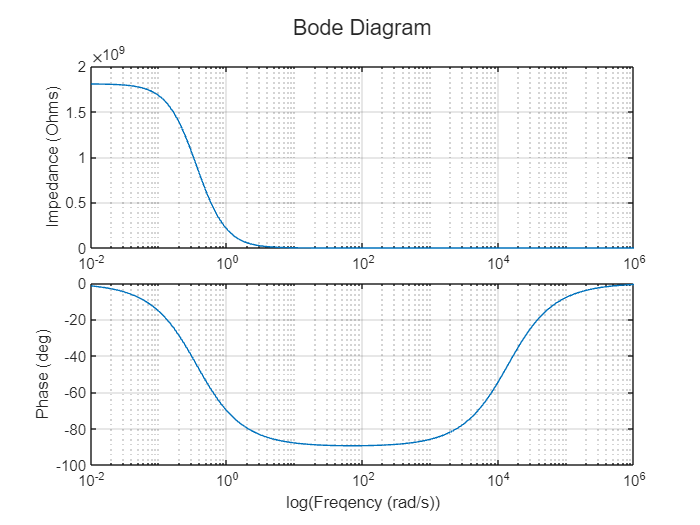

% 2.2e(4)
close all

Rpar = (Rs*Rct)/(Rs+Rct);

freq = logspace(-2,6,100);

Z_faradaic = Rs*(1i*freq+(1/(Rpar*Cdl)))./(1i*freq+(1/(Rct*Cdl)));

tiledlayout(2,1,'TileSpacing','tight')

ax1 = nexttile;
semilogx(freq,real(Z_faradaic))
grid on
ylabel("Impedance (Ohms)");

ax2 = nexttile;
semilogx(freq,rad2deg(angle(Z_faradaic)))
grid on
xlabel("log(Freqency (rad/s))");
ylabel("Phase (deg)");

sgtitle("Bode Diagram")

% 2.2f(1)

% Ignoring Rct implies that the electrode is non-Faradaic, so voltage can
% be computed as follows:

I = 80e-6; % Current (A)
C = 1.54e-9; % Capacitance (F)
t = 1e-3; % Pulse width
V_drop = I*t/C

V_drop = 51.9481

% The voltage drop is 51.9 V, which is greater than the upper bound of the
% water windoe (0.9 V). Therefore, stimulation would result in water
% electrolysis.

% 2.2f(2)

% In order to not induce water electrolysis, we must obey the constraint
% V<(I/C)t. Solving this inequality for I will provide us with our current
% amplitude limit:
V = 0.9; % V
C = 1.54e-9; % Capacitance (F)
t = 1e-3; % Pulse width
I = (V*C)/t

I = 1.3860e-06

% The current amplitude limit to ensure that ater electrolysis is not
% induced is 1.38 uA.

% 2.2f(3)

% Since this electrode is non-Faradaic, the voltage can be computed from
% the equation V(t) = IR_s + (I/C). Increasing ESA by a roughness factor of
% 10 would increase the capacitance, C, by a factor of 10. Therefore, V
% will be decreased for all values of t and I. A decrease in the magnitude
% of V will cause the CV to be more narrow horizontally and cause the water
% window limits to move closer to 0.

% 2.2g(1)

% We know that Q = IT, where I is the current magnitude and T is the pulse
% width. Plugging this value into Shannon's equation and solving for D provides us
% with:
I = 80; % Current (uA)
T = 1e-3; % Pulse duration (s)
D = 10^(1.5-log10(I*T))

D = 395.2847

% The neural damage limit for this design in 395.3 uC/cm^2.

% 2.2g(2)

% From 2.2g(1), we know the neural damage limit is 395.3 uC/cm^2. From the
% problem description, we know the electrochemical safety limit for a
% platinum electrode is 0.35 mC/cm^2. Converting to the same units shows us
% that the ESL (0.35 mC/cm^2) < NDL (0.395 mC/cm^2). Therefore, the
% electrochemical safety limit is lower than the neural damage limit.

% 2.2g(3)
% Since the ESL < NDL, the lower bound of stimulation current is determined 
% by the ESL, 0.35 mC/cm^2, and the upper bound of stimulation current is
% determined by the NDL, 0.395 mC/cm^2 and can be computed as follows:

ESL_plat = 0.35e-3; % C/cm^2
A = pi*(30e-4)^2;   % cm^2
T = 1e-3;           % s
I_min = (ESL_plat*A/T)*10^6

I_min = 9.8960

I_max = D*A/T

I_max = 11.1764

% Therefore, the range of stimulation current at a stimulation pulse width
% of 1 ms for the Pt electrode would be [9.896uA 11.1764uA]

% 2.2g(4)

% Sincethe NDL (0.395 mC/cm^2) < ESL_IrOx (4 mC/cm^2), so the lower bound
% will be determined by the NDL and the upper bound will be determined ESL:

A = pi*(30e-4)^2;   % cm^2
T = 1e-3;           % s
I_max = D*A/T

I_max = 11.1764

ESL_IrOx = 4e-3; % C/cm^2
I_min = (ESL_IrOx*A/T)*10^6

I_min = 113.0973

% Therefore, the range of stimulation current at a stimulation pulse width
% of 1 ms for the IrOx electrode would be [11.1764uA 113.09uA]